# **Εργασία Ειδικά Συστήματα Πλοίου**

## **Ερώτημα 1: **Ανάλυση των δεδομένων με τη χρήση διαφόρων γραφικών παραστάσεων

clear all
warning("off")
% load all data
Data2024 = readtable("Data2024.csv",'TrailingDelimitersRule','ignore')

Data2024 = 451228×11 table
    Time     NOx     FuelConsumption    lambda    ExhaustGasMassFlow    IntakePressure    TorqueReference    Rot_Speed    EngineTorque    EGRCommand    ExhaustGasTemperature
    ____    _____    _______________    ______    __________________    ______________    _______________    _________    ____________    __________    _____________________

       0    167.5          2.6          7.1378            239                 4                 10            800.46          4.034           0                152.31        
    0.01    167.5          2.6          7.1378            239               

% Extract the units
% Open the file for reading
fid = fopen('Data2024.csv', 'r');
% Read the header line and discard it
fgetl(fid);
% Read the next line as a string
second_line = fgetl(fid);
% Close the file
fclose(fid);
% Split the string into cell array of units
units = strsplit(second_line, '\t');
% Convert cell array to array
units = string(units);

clearvars fid second_line ans

% Initialize the fieldnames of the data
fieldnames = Data2024.Properties.VariableNames

fieldnames = 1×11 cell array
    {'Time'}    {'NOx'}    {'FuelConsumption'}    {'lambda'}    {'ExhaustGasMassFlow'}    {'IntakePressure'}    {'TorqueReference'}    {'Rot_Speed'}    {'EngineTorque'}    {'EGRCommand'}    {'ExhaustGasTemperature'}


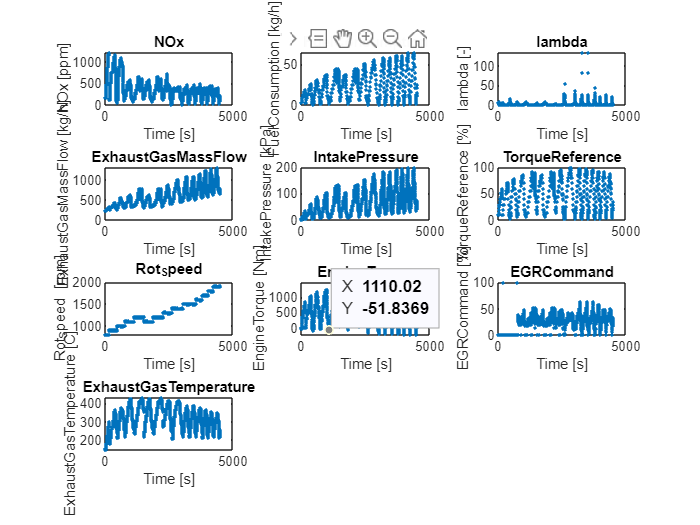

% Initialize a struct to store values
data = struct();

% Loop through each column
for i = 1:numel(fieldnames)
    % Extract values of the current column
    data.(fieldnames{i}) = table2array(Data2024(:, fieldnames{i}));
end

% Define the number of plots
num_plots = numel(fieldnames) - 1; % Excluding the first column

% Define the number of rows and columns for subplots
num_rows = ceil(sqrt(num_plots));
num_cols = ceil(num_plots / num_rows);

% Create a new figure
figure;

% Plot each column against the "Time" column on subplots
for i = 2:numel(fieldnames) % Start from the second column
    subplot(num_rows, num_cols, i-1); % Create subplot
    plot(data.Time, data.(fieldnames{i}),'.');
    title(fieldnames{i}); % Set title as column name
    xlabel('Time [s]'); % X-axis label
    ylabel(sprintf('%s %s', fieldnames{i}, units{i})); % Y-axis label
end

clearvars num_cols num_rows num_plots i ans

#### Ανάλυση Δεδομένων

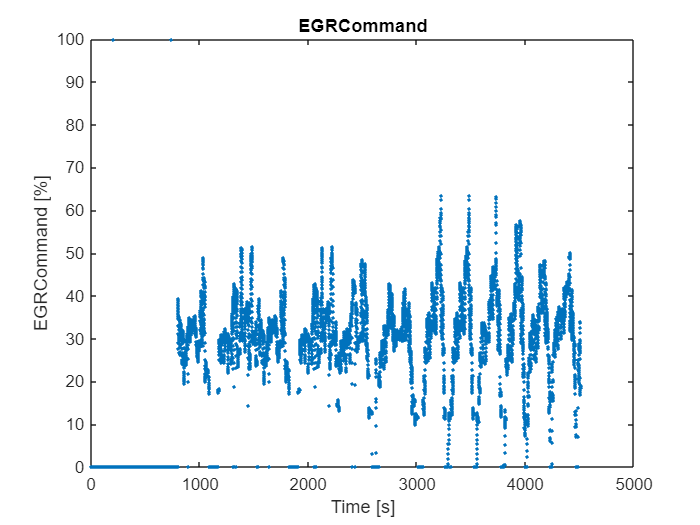

i = 10;
figure; % Create a new figure
plot(data.Time, data.(fieldnames{i}),".");
title(fieldnames{i}); % Set title as column name
xlabel('Time [s]'); % X-axis label

% Concatenate field name with unit and set it as Y-axis label
ylabel(sprintf('%s %s', fieldnames{i}, units{i}));

clearvars i

**NOx:** Έχουν περιοδική κίνηση με απόσβεση, φθίνουσα. Περίοδος είναι 225s. Η μέση τιμή μικραίνει με την πάροδο του χρόνου, ξεκινάει από 600 ppm και καταλήγει εως και 200 ppm.

**Fuel Consumption:** Έχουν περιοδική κίνηση με αυξανόμενο πλάτος (ίδια περίοδος με ΝΟx 180-405s η πρώτη περίοδος). Οι μέγιστες τιμές ξεκινάνε από 20kg/h και φτάνουν ως 65kg/h.

**Λάμδα:** Έχει τιμές μικρότερες του 20 εως την στιγμή 2619s που γίνεται το πρώτο peak. Έχει συνολικά 8 peaks με τα μέγιστα να ξεπερνάνε την τιμή 130.

## Ερώτημα 2: Φιλτράρισμα και μετασχηματισμός των δεδομένων.

Το παρακάτω μπορεί να χρησιμοποιηθεί για να παράγουμε τα φιλτραρισμένα δεδομένα, επιλέγοντας κάθε φορά το σωστό threshold.

% % Initialize a struct to store filtered values
% data_filt = struct();
% time_filt = struct();
% 
% % Store thresholds
% thresholds = zeros(1,length(fieldnames));
% 
% clc
% 
% for j = 2:numel(fieldnames)
%     [filteredData, filteredTime,threshold] = chauvenetFilter(Data2024,fieldnames,units,j);
%     data_filt.(fieldnames{j}) = filteredData;
%     time_filt.(fieldnames{j}) = filteredTime;
%     thresholds(1,j) = threshold;
% end
% clearvars j threshold filteredData filteredTime

#### Αποθήκευση Φιλτραρισμένων Δεδομένων

Για να αναπαράγουμε τα παραπάνω δεδομένα θα αποθηκεύσουμε τα thresholds που παράγαμε και θα μπορούμε να φορτώνουμε ξανά τα παραπάνω δεδομένα.

% writematrix(thresholds,"thresholds.csv");
% clearvars ans 

#### Ανάκτηση Δεδομένων

Για να ξαναποκτήσουμε τα φιλτραρισμένα δεδομένα, μπορούμε να τρέξουμε τον παρακάτω κώδικα:

% Initialize a struct to store filtered values
data_filt = struct();
time_filt = struct();

% Read thresholds from the CSV file
thresholds = readmatrix('thresholds.csv');

clc

for j = 2:numel(fieldnames)
    [filteredData, filteredTime, ~] = chauvenetFilter2(Data2024, fieldnames, units, j, thresholds(j));
    data_filt.(fieldnames{j}) = filteredData;
    time_filt.(fieldnames{j}) = filteredTime;
end

clearvars filteredData filteredTime j

Για την επιλογή των **thresholds**:

function [filteredData, filteredTime, threshold] = chauvenetFilter(Data, fieldnames, units, i)

    data = Data.(fieldnames{i});
    time = Data.Time;
    
    redo = true;
    while redo
        % Calculate mean and standard deviation
        mu = mean(data);
        sigma = std(data);

        % Calculate residuals
        residuals = abs(data - mu);

        % Calculate probability
        p = 1 - 0.5 * (1 + erf(residuals / (sigma * sqrt(2))));
        p_mean = mean(p);
        
        % Plot unfiltered data
        figure;
        subplot(2,2,1); % Plot on the first row, first two columns
        plot(time, data);
        title(fieldnames{i}); % Set title as column name
        xlabel('Time [s]'); % X-axis label
        ylabel(sprintf('%s %s', fieldnames{i}, units{i})); % Concatenate field name with unit and set it as Y-axis label

        % Plot unfiltered data
        subplot(2,2,2); % Plot on the second row, first column
        plot(time, data,".");
        title(fieldnames{i}); % Set title as column name
        xlabel('Time [s]'); % X-axis label
        ylabel(sprintf('%s %s', fieldnames{i}, units{i})); % Concatenate field name with unit and set it as Y-axis label

        % Prompt user for threshold
        threshold = input(['Enter the threshold probability (mean is ', num2str(p_mean), '): ']);

        % Apply Chauvenet's Criterion (threshold probability)
        outliers = p < threshold;

        % Remove outliers
        filteredData = data(~outliers);
        filteredTime = time(~outliers);

        % Plot filtered data
        subplot(2,2,[3,4]); % Plot on the second row, second column
        plot(filteredTime, filteredData);
        title(['Filtered ', fieldnames{i}]); % Set title as column name
        xlabel('Time [s]'); % X-axis label
        ylabel(sprintf('%s %s (Filtered)', fieldnames{i}, units{i})); % Concatenate field name with unit and set it as Y-axis label
        
        % Ask if the user wants to redo
        redo_prompt = input('Do you want to redo the filtering? (yes/no): ', 's');
        if strcmpi(redo_prompt, 'no')
            redo = false;
        end
    end
end

Για την **ανάκτηση** των φιλτραρισμένων δεδομένων:

function [filteredData, filteredTime, threshold] = chauvenetFilter2(Data, fieldnames, units, i, threshold)

    data = Data.(fieldnames{i});
    time = Data.Time;
    
    % Calculate mean and standard deviation
    mu = mean(data);
    sigma = std(data);

    % Calculate residuals
    residuals = abs(data - mu);

    % Calculate probability
    p = 1 - 0.5 * (1 + erf(residuals / (sigma * sqrt(2))));
    p_mean = mean(p);

    % Apply Chauvenet's Criterion (threshold probability)
    outliers = p < threshold;

    % Remove outliers
    filteredData = data(~outliers);
    filteredTime = time(~outliers);
end
